x = [-.04, .93, 1.95, 2.90, 3.83, 5, 5.98, 7.05, 8.21, 9.08, 10.09];
y = [-8.66, -6.44, -4.36, -3.27, -0.88, 0.87, 3.31, 4.63, 6.19, 7.40, 8.85];
n = numel(x)

n = 11

desv_std = zeros(1, n-1);
for i = 1: n-1
    [~, ~, s] = PoliMulti(x, y, i);
    i
    desv_std(i) = s;
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

desv_std'

ans =     0.1971
    0.0762
    0.2005
    0.2195
    0.2176
    0.2683
    0.2866
    0.3204
    0.3574
    0.0212


[min_desv, i] = min(desv_std)

min_desv = 0.0212

i = 10

p = PoliMulti(x, y, i)

p =     0.0001   -0.0029    0.0620   -0.7504    5.5653  -26.0222   75.9135 -131.1663  118.4679  -37.5339  -10.3593


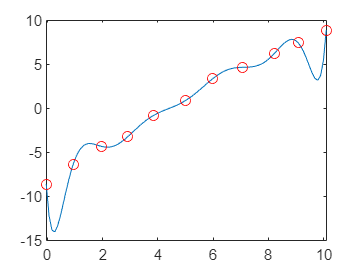

t = linspace(min(x),max(x));
plot(t, polyval(p, t));
hold on
plot(x, y, 'ro')
hold off